body = imread('masked.png')

body = 240×320 uint8 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   207   206   206   204   206   200   203   201   199   199   193   196   197   199   198   201   199   198   199   201   204   205   204   206   206   206   204   203   199
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   205   206   207   208   204   201   202   205   200   196   195   196   197   200   201   201   196   197   196   198   202   204   204   208   204   205   202   202   201
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   206   205   208   206   202   204   201   200   196   197   195   200   200   199   198   198   194   196   198   203   204   205   206   205   205   201   201   200
     0     0     0     0     0     0     0     0     0     0     0   

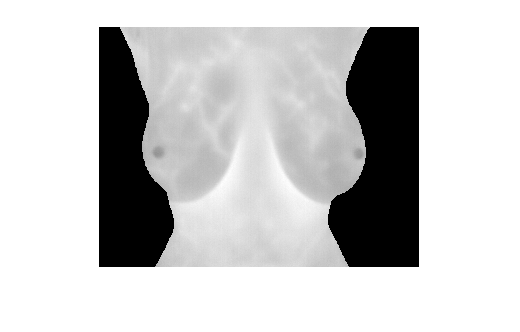

imshow(body)


output = adaptthresh(body, 0.3, "NeighborhoodSize", 15 , 'ForegroundPolarity','bright', "Statistic", "median")

output =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000

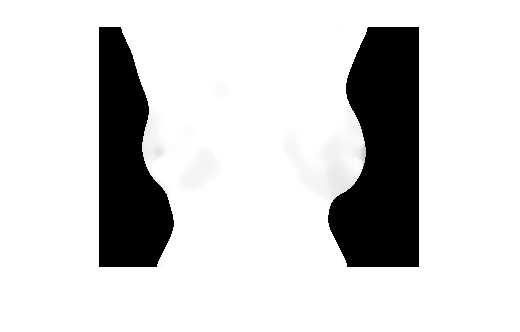

imshow(output)

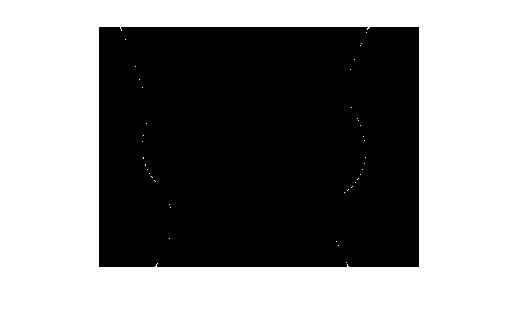

BW = imbinarize(body,output);
imshow(BW)